# **2108332 Adjustment Computation**

## **LAB 6** Observation equations

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

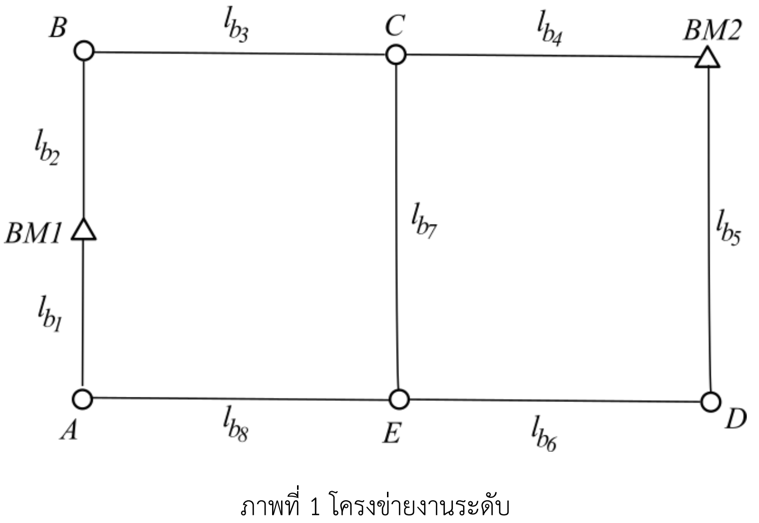

ภาพที่ 1 แสดงการรังวัดโครงข่ายงานระดับ ลูกศรในภาพแสดงถึงทิศทางการรังวัด ผลการรังวัดแสดงในตารางต่อไปนี้

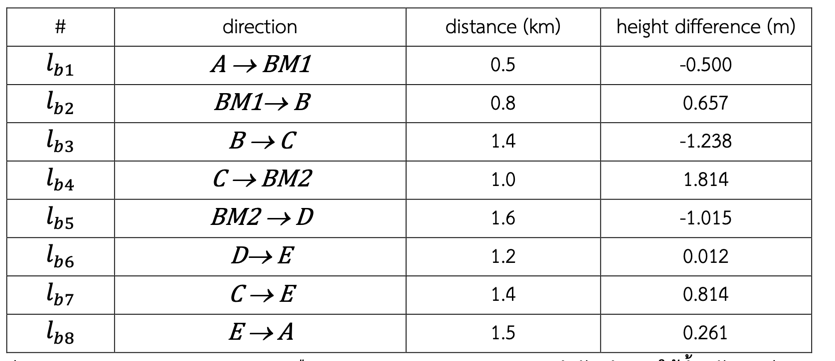

#### ค่าความสูงของจุด $BM1$ และ $BM2$ คือ 29.499 ม. และ 30.737 ม. ตามลำดับ กำหนดให้น้ำหนักของค่ารังวัดแต่ละค่าเป็นอิสระต่อกัน และแปรผกผันกับระยะทาง เพื่อปรับแก้ค่ารังวัดโดยวิธีกำลังสองน้อยที่สุดแบบใช้สมการเงื่อนไข สคริปต์จะต้องแสดงค่ารังวัดที่ปรับแก้แล้ว และ ค่าระดับของจุด $A, B, C$ และ $D$

clear
format long g
BM1 = 29.499;
BM2 = 30.737;
lb = [-0.500;0.657;-1.238;1.814;-1.015;0.012;0.814;0.261];
P = [1/0.5;1/0.8;1/1.4;1/1;1/1.6;1/1.2;1/1.4;1/1.5];
P_diagonal = diag(P);

B = [1 1 1 0 0 0 1 1;
    0 0 0 1 1 1 -1 0;
    0 1 1 1 0 0 0 0];
C = [0;
    0;
    BM1-BM2];

W = B * lb + C;
v_1 = - (P_diagonal^-1) * B' * ((B * (P_diagonal^-1) * B')^-1) * W;
L_a = lb + v_1

L_a =         -0.499503040973111
         0.658318822023047
         -1.23569206145967
          1.81537323943662
         -1.01385019206146
        0.0128623559539053
         0.814385403329065
         0.262490877080666


H_A = BM1 - L_a(1)

H_A =           29.9985030409731


H_B = L_a(2) + BM1

H_B =            30.157318822023


H_C = L_a(3) + H_B

H_C =           28.9216267605634


H_D = L_a(5) + BM2

H_D =           29.7231498079385


H_E = L_a(6) + H_D

H_E =           29.7360121638924


#### 2. การรังวัดมุมรอบจุด ดังภาพได้ค่าตารางต่อไปนี้

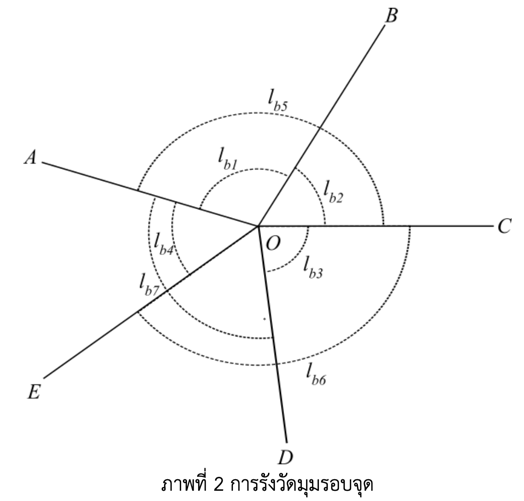

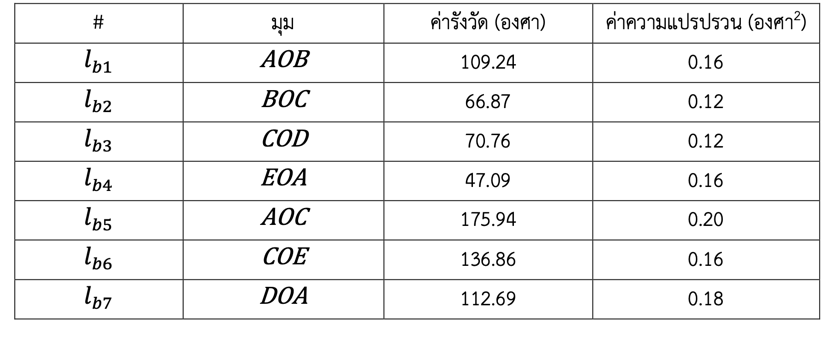

#### กำหนดให้ค่ารังวัดทั้งหมดไม่มีสหสัมพันธ์ซึ่งกันและกัน ให้เขียนสคริปต์ MATLAB เพื่อปรับแก้ค่ารังวัดโดยวิธีกำลังสองน้อยที่สุดแบบใช้สมการเงื่อนไข สคริปต์จะต้องแสดงเศษคงเหลือ (v) และค่ารังวัดที่ปรับแก้แล้ว

clear
format long g
P = [0.16;0.12;0.12;0.16;0.20;0.16;0.18];
P_diagonal = diag(P);
lb = [109.24;
    66.87;
    70.76;
    47.09;
    175.94;
    136.86;
    112.69];

B = [1 1 0 1 0 1 0;
    1 1 1 0 0 0 1;
    0 0 0 1 1 1 0];
C = [-360;
    -360;
    -360];

W = B * lb + C;

v = - (P_diagonal^-1) * B' * ((B * (P_diagonal^-1) * B')^-1) * W

v =       -0.00725543478262851
      -0.00967391304350466
         0.274157608695679
       -0.0215353260869629
          0.15307065217394
       -0.0215353260869629
         0.182771739130452


La = lb + v

La =           109.232744565217
          66.8603260869565
          71.0341576086957
           47.068464673913
          176.093070652174
          136.838464673913
           112.87277173913
